clear
close all
addpath("..\data\geojsonR01\")
addpath("..\data\matlabMobile\")

% センサーデータの読み込みとまとめ
load("himeji2shinosaka.mat")

sensor = synchronize(Acceleration,AngularVelocity,MagneticField,Orientation,Position,'union','previous');
sensor = rmmissing(sensor);
% 時間を初期値を0にする
sensor.Timestamp = sensor.Timestamp-sensor.Timestamp(1);

%センサーの時間切り出し
sensor = sensor(1:100000,:)

sensor = 100000×18 timetable
    Timestamp    X_Acceleration    Y_Acceleration    Z_Acceleration    X_AngularVelocity    Y_AngularVelocity    Z_AngularVelocity    X_MagneticField    Y_MagneticField    Z_MagneticField    X_Orientation    Y_Orientation    Z_Orientation    latitude    longitude    altitude    speed    course    hacc
    _________    ______________    ______________    ______________    _________________    _________________    _________________    _______________    _______________    _______________    _____________    _____________    _____________    ________    _________    ________    _____    ______    ____

    00:00:00        -0.13966          -0.10703           9.6308             0.00216             0.001051             -0.003185            -34.227            -17.518            -18.071           113.82          -0.19071         -0.26199        34.827      134.69       18.871       0      258.4      10 
    00:00:00        -0.13966          -0.10703           9.63

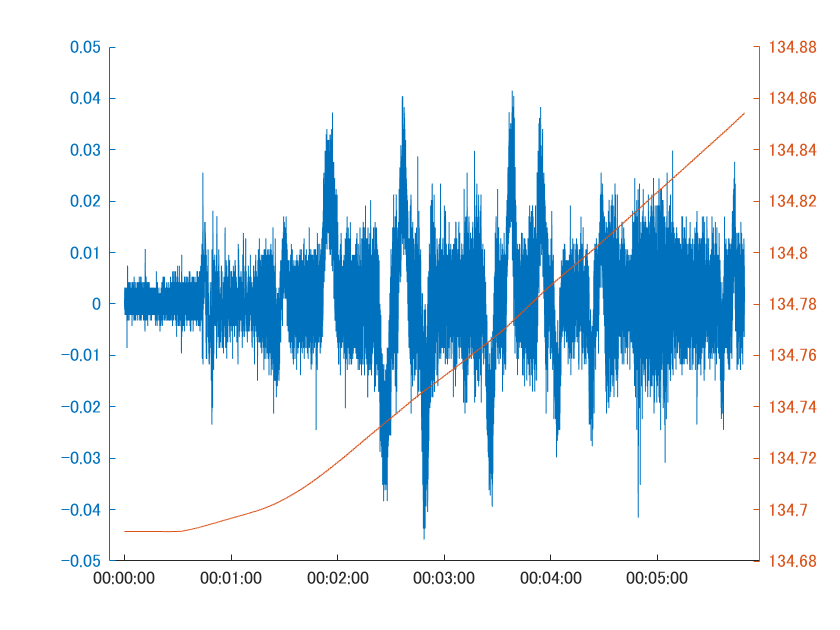

figure
hold on
yyaxis left
plot(sensor.Timestamp,sensor.Y_AngularVelocity)
yyaxis right
plot(sensor.Timestamp,sensor.longitude)
hold off

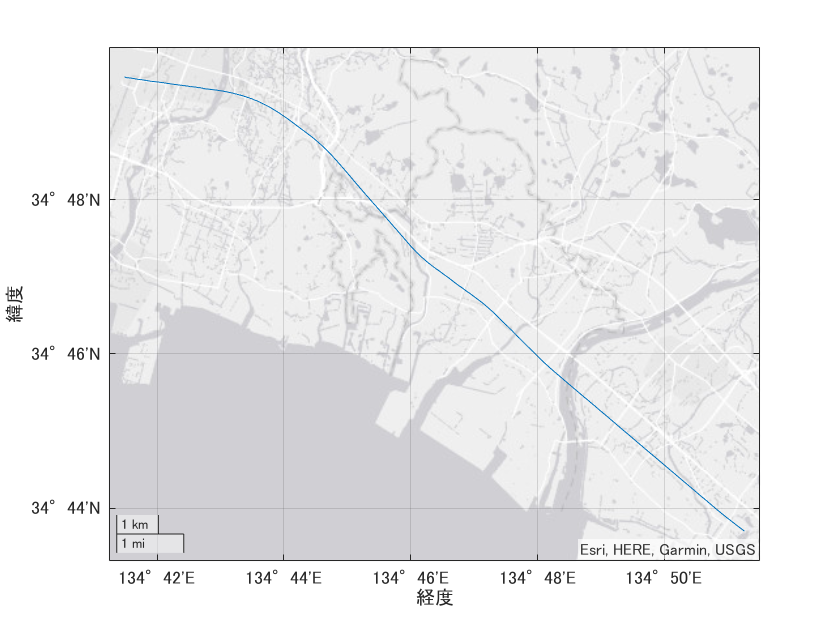

figure
geoplot(sensor.latitude,sensor.longitude)

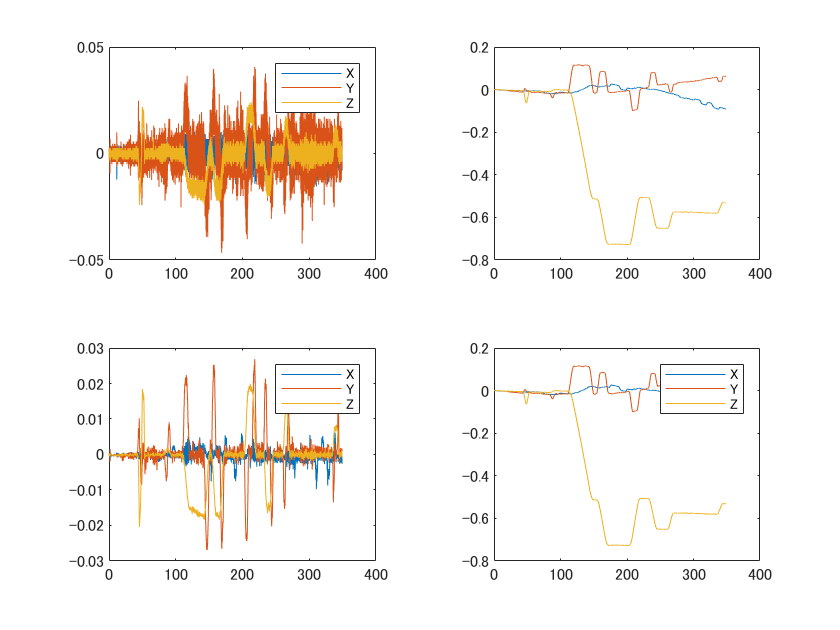

%%　角度についてのデータ
windowsize = 100;
% バイアスの確認
X_AngVelBias = mean(sensor.X_AngularVelocity(1:200,1));
Y_AngVelBias = mean(sensor.Y_AngularVelocity(1:200,1));
Z_AngVelBias = mean(sensor.Z_AngularVelocity(1:200,1));

% 角度の修正
secondsTime = seconds(sensor.Timestamp);
X_AngVel = sensor.X_AngularVelocity-X_AngVelBias;
Y_AngVel = sensor.Y_AngularVelocity-Y_AngVelBias;
Z_AngVel = sensor.Z_AngularVelocity-Z_AngVelBias;


figure
tiledlayout(2,2);
nexttile;
AngVel = [X_AngVel,Y_AngVel,Z_AngVel];
plot(secondsTime,AngVel)
legend(["X","Y","Z"])

%角度変化
nexttile
Ang = cumtrapz(secondsTime,AngVel,1);
% 下の方法と同義
% X_Ang = cumtrapz(secondsTime,X_AngVel)
% Y_Ang = cumtrapz(secondsTime,Y_AngVel)
% Z_Ang = cumtrapz(secondsTime,Z_AngVel)
plot(secondsTime,Ang)

%移動平均の移動プロット
nexttile;
movmeanAngVel = movmean(AngVel,windowsize);
plot(secondsTime,movmeanAngVel)
legend(["X","Y","Z"])

nexttile;
movmeanAng = cumtrapz(secondsTime,movmeanAngVel,1);
plot(secondsTime,movmeanAng)
legend(["X","Y","Z"])